## Generate Velocity Field

Perlin Noise Settings

ammountN    =  39.9;
n_tiles     =     10;
n_octaves   =   28;
persistence = 0.796;
seed        =   32;

Horizontal Force Settings

ammountH    =  483;

Object Settings

ammountO    =  0.5;
sigma       =  64.05 ;

Simulation Settings

size        =  1401;
n_particles = 47000;
vel         = 13.86;
step        =     112;
END_TIME =     40;

Generate Grid

x = (1:size)/size-1/2;
y = transpose((1:size)/size-1/2);

Generate Perlin Noise [1]

rng(seed);
Psi_N     = zeros(size);
idxs      = 1:n_octaves;
max_amp   = sum(persistence.^(idxs-1));

for i = idxs
    Psi_N = Psi_N + ...
        imresize(rand(n_tiles*i), ...
                [size size],"cubic")*...
        persistence^(i-1)/...
        max_amp;
end
Psi_N = Psi_N/n_tiles;

Generate Horizontal Force Potential

Psi_H = x+0*y;

Generate Object Potential

Object = imresize( ...
         rgb2gray(imread("Object.png"))...
        ,[size,size]);
Edge = edge(Object);
Psi_O = imgaussfilt(transpose( ...
        double(Object)),sigma);

Superposition of Potentials

Psi = vel*(Psi_N*ammountN+Psi_H*ammountH+Psi_O*ammountO);

Generate Velocity Field [2]

[dPsidx,dPsidy] = gradient(Psi);
vx =   dPsidx*size;
vy =  -dPsidy*size;

Visualize Potential

%{
fig = figure('Position',[0,0,400,200]);
tiledlayout(1,2);
nexttile;
imagesc(Psi);
nexttile;
contour(transpose(Psi));
%}

## Particle Simulation

Initialization

dt = 1/60;
px = size*rand(n_particles,1)*0.1;
[py,pidxs] = sort(size*rand(n_particles,1));
pc = 1:n_particles;
pc = pc(pidxs);

Simulation

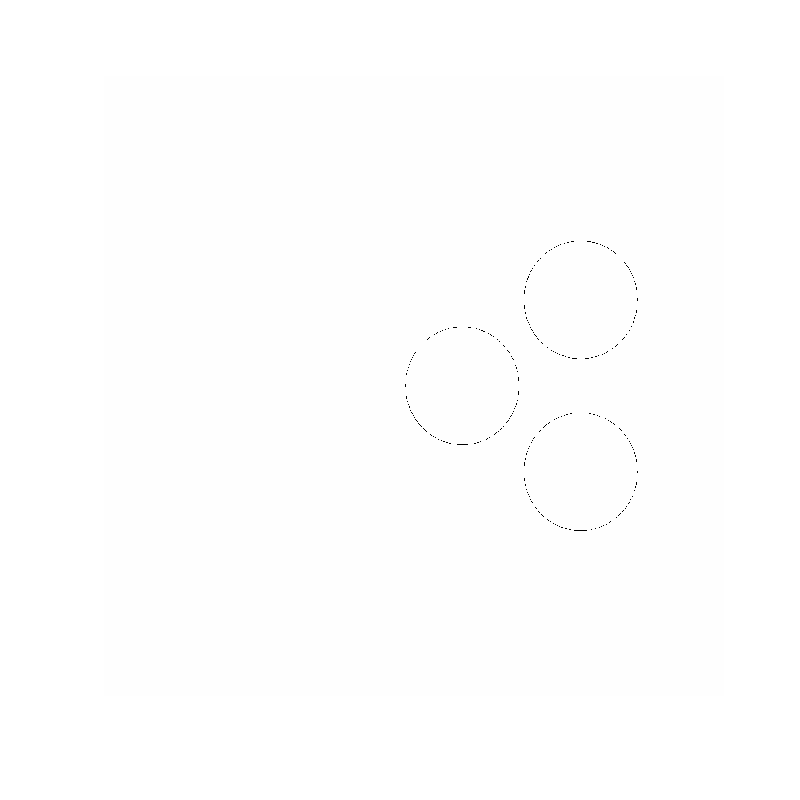

fig = figure('Position',[0,0,800,800]);
for t = 1:END_TIME*step
    px_grid = round(px);
    py_grid = round(py);
        
    px_grid(px_grid<1) = 1;
    px_grid(size<px_grid) = size;

    py_grid(py_grid<1) = 1;
    py_grid(size<py_grid) = size;
    
    if mod(t,step) == 0    
        cla
        hold on
        image(255*(1-Edge));
        colormap gray;
        scatter(px,py,1,pc,".","CData",cool(n_particles));
        xlim([0 size]);
        ylim([0 size]);
        pbaspect([1 1 1]);
        axis off
        hold off
        drawnow;
    end
        
    for i = 1:n_particles
        pvx = vx(px_grid(i),py_grid(i));
        pvy = vy(px_grid(i),py_grid(i));
        
        px(i) = px(i) + pvx * dt / step;
        py(i) = py(i) + pvy * dt / step;
    end 
end

## Reference

[1] Perlin Noise, [https://web.archive.org/web/20080724063449/http://freespace.virgin.net/hugo.elias/models/m_perlin.htm](https://web.archive.org/web/20080724063449/http://freespace.virgin.net/hugo.elias/models/m_perlin.htm)

[2] Bridson, R., Houriham, J., & Nordenstam, M. (2007). Curl-noise for procedural fluid flow. *ACM Transactions on Graphics (ToG)*, *26*(3), 46-es.